y = [24,26,27,30,32,33,36,40,41,44];
plot(y,'*-')
hold on
y=y';
len=length(y);
alpha=0.4;
dy=diff(y);  %diff既可以对函数求导，还可以求一阶向前差分
dy=[0;dy];%后面还需要向后差分还原，加'0'补位
dyhat(2)=dy(2);
for i=2:len
    dyhat(i+1)=alpha.*dy(i)+(1-alpha).*dyhat(i);
end
for i=1:len
    yhat(i+1)=dyhat(i+1)+y(i);
end
yhat(1)=NaN;
yhat   %第11个就是1987的预测值

yhat =        NaN   26.0000   28.0000   28.6000   32.1600   34.0960   34.6576   38.1946   42.9167   43.1500   46.4900


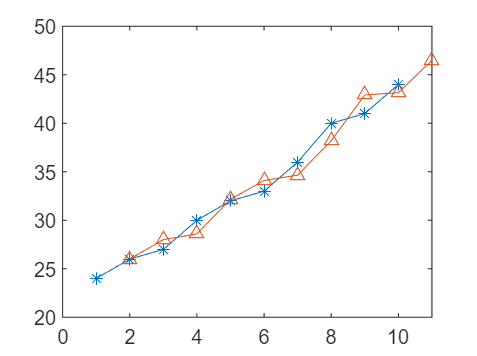

plot(yhat,'^-')
hold off